Santeri Saariokari 253345

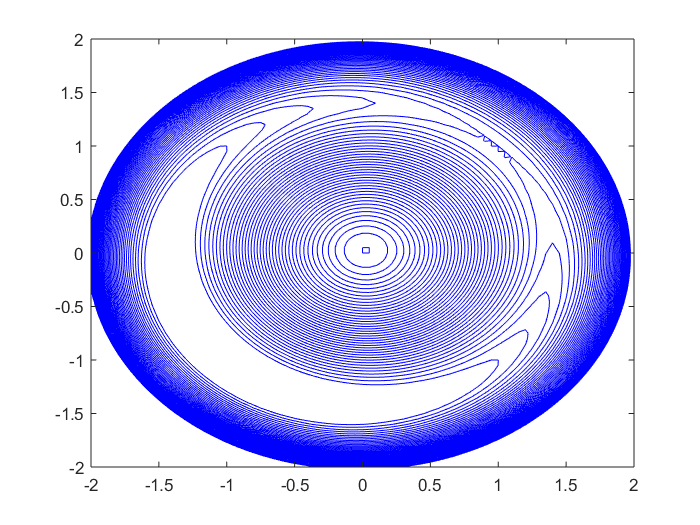

pobj = VideoWriter('contour', 'mpeg-4');
open(pobj);

[x, y] = meshgrid(-2:0.025:2);
for m = 0.5:0.05:10
    z = x+y+0.5.*m.*(x.^2+y.^2-2).^2;
    contour(x, y, z, 0:.5:20, 'Color', 'b');
    frame = getframe;
    writeVideo(pobj, frame);
end


close(pobj)